dEall = zeros(4,24);

modename = {'White LED','Standard LED','General','GB LED'};

for mode = 1:4
    colstart = (mode-1)*3 + 1;

    cc = ColorConversionClass
    load('spyder0606','spyder')
    XYZ_cck = spyder(:,colstart:colstart+2);
    LAB_cck = cc.XYZ2lab(XYZ_cck,XYZ_cck(19,:));

    load('colorchecker_test_result_hp')
    spec = zeros(24,41);
    for i = 1:24
        s = spd_ol490_24{i};
        s = s(1:10:end);
        spec(i,:) = s;
    end

    % XYZ is 24x3
    XYZ_ol490 = cc.spd2XYZ(spec');
    LAB_ol490 = cc.XYZ2lab(XYZ_ol490,XYZ_ol490(19,:));

    for i = 1:24
        [dE00 dE94 dEab] = cc.LAB2dE(LAB_cck(i,:)',LAB_ol490(i,:)');
        dE(i) = dE00;
        dEall(mode,:) = dE;
    end

    subplot(2,2,mode)
    bar(dE)
    xlabel('Color Patch #')
    ylabel('dE00')    
    title(modename{mode})
end

cc =   ColorConversionClass with properties:

    Property1: []


cc =   ColorConversionClass with properties:

    Property1: []


cc =   ColorConversionClass with properties:

    Property1: []


cc =   ColorConversionClass with properties:

    Property1: []


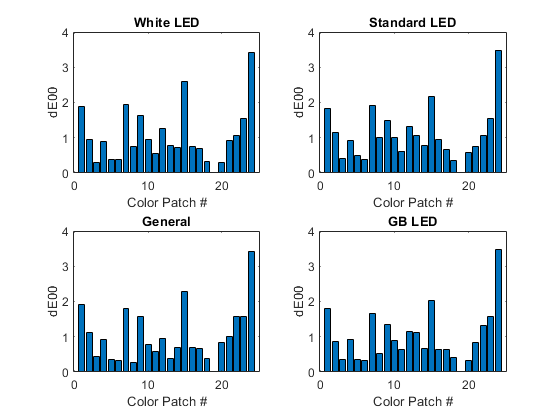

saveas(gcf,'compare_dE_2x2.png')


clf
hold on
plot(dEall(1,:),'o:')
plot(dEall(2,:),'x:')
plot(dEall(3,:),'+:')
plot(dEall(4,:),'^:')
xlabel('Color Patch #')
ylabel('dE00')
legend('White LED','Standard LED','General','GB LED')
legend('Location','northwest')

dEmean = mean(dEall,2)

dEmean =     1.0398
    1.0808
    1.0208
    0.9943



dEstd = std(dEall,1)

dEstd =     0.0466    0.1175    0.0483    0.0180    0.0578    0.0302    0.1078    0.2746    0.1092    0.0858    0.0323    0.1371    0.2922    0.0408    0.2111    0.1136    0.0156    0.0339         0    0.2157    0.0973    0.2077    0.0098    0.0309


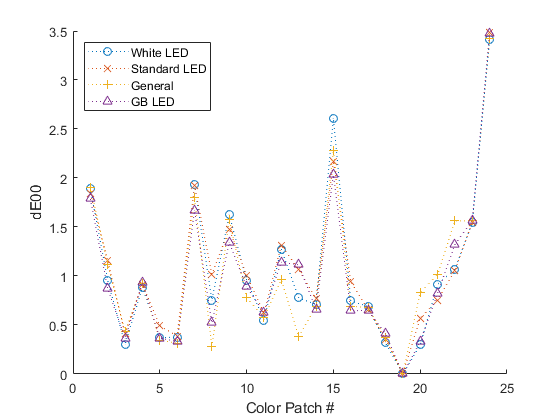

saveas(gcf,'compare_dE.png')


mode = 2

mode = 2

colstart = (mode-1)*3 + 1;

cc = ColorConversionClass

cc =   ColorConversionClass with properties:

    Property1: []


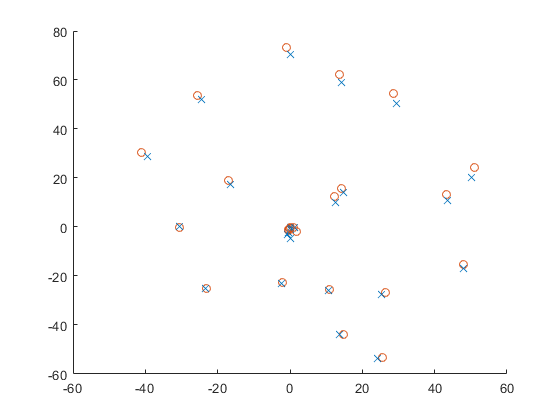

load('spyder0606','spyder')
XYZ_cck = spyder(:,colstart:colstart+2);
LAB_cck = cc.XYZ2lab(XYZ_cck,XYZ_cck(19,:));

clf
hold on
plot3(LAB_cck(:,2),LAB_cck(:,3),LAB_cck(:,1),'x')
plot3(LAB_ol490(:,2),LAB_ol490(:,3),LAB_ol490(:,1),'o')


mode = 2

mode = 2

colstart = (mode-1)*3 + 1;

cc = ColorConversionClass

cc =   ColorConversionClass with properties:

    Property1: []


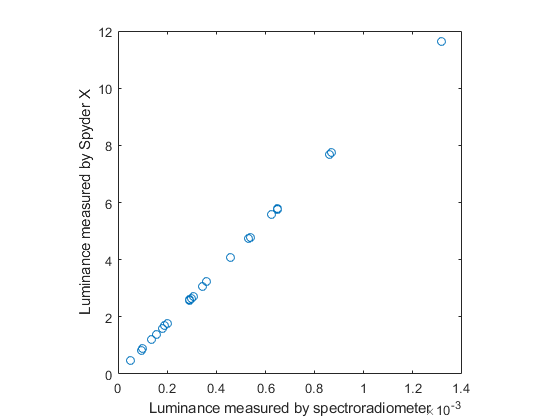

load('spyder0606','spyder')
XYZ_cck = spyder(:,colstart:colstart+2);

Y_cck = XYZ_cck(:,2);
Y_ol490 = XYZ_ol490(:,2);


clf
plot(Y_ol490,Y_cck,'o')
xlabel('Luminance measured by spectroradiometer')
ylabel('Luminance measured by Spyder X')
axis square
saveas(gcf,'compare_luminance.png')